**Assignment**

Aside from e-cigarettes, another alternative to tradition cigarettes are carbon heated tobacco products (CHTP).  These heat the tobacco leaves to a lower temperature than cigarettes, but still expose you to the addictive nicotine.  Carine and her team wanted to examine the different in effect these products have on human cells.  So they exposed some cells to the aerosol of CHTP, other cells to conventional cigarettes.  They measured the gene expression with microarrays.  This dataset is provided as an excel file 'Cigarette_exposure.xlsx' with two sheets.  The first sheet has a column per sample, and one row per gene (labelled with HNGC gene symbol), the second sheet has a row per sample describing the conditions that sample was exposed to.  The crucial column is 'product category', which indicates if the sample was exposed to the aerosol from CHTP, a conventional cigarette or nothing.  Analyse this dataset to see which genes are differentially expressed with both products.

If you want to find out more about the study see [https://www.ebi.ac.uk/biostudies/arrayexpress/studies/E-MTAB-6721](https://www.ebi.ac.uk/biostudies/arrayexpress/studies/E-MTAB-6721)

# **Extraction of data from the Excel**

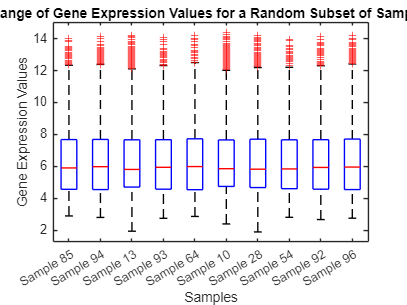


filename = 'Cigarette_exposure.xlsx';

data = readtable(filename, 'Sheet', 'Data', 'PreserveVariableNames', true);
metadataTable = readtable(filename, 'Sheet', 'Metadata', 'PreserveVariableNames', true);

geneExpressionValues = data{2:end, 2:end}; 
geneNames = data{2:end, 1};

rng('default'); % For reproducibility
randomIndices = randperm(size(geneExpressionValues, 2), 10); % Select 10 random samples

% Extract the subset of gene expression data
subsetGeneExpression = geneExpressionValues(:, randomIndices);

% Create sample labels for the random subset
sampleLabels = arrayfun(@(x) sprintf('Sample %d', x), randomIndices, 'UniformOutput', false);

%box plot of the selected gene expression values
figure;
boxplot(subsetGeneExpression, 'Labels', sampleLabels);
title('Range of Gene Expression Values for a Random Subset of Samples');
xlabel('Samples');
ylabel('Gene Expression Values');

This box plot represents the range of gene expression values for a random subset of samples on the x-axis. The y-axis shows the gene expression values. Let’s analyze this visualization in terms of its statistical features:

## **Interquartile Range (IQR)**:

- The blue boxes represent the IQR, which is the range between the first quartile (Q1, 25th percentile) and the third quartile (Q3, 75th percentile). It encompasses the middle 50% of the data points.

- The red line inside each box represents the median (50th percentile), which is the central value of the dataset.

## **Whiskers**:

- The black whiskers extend to the smallest and largest values within 1.5 times the IQR below Q1 and above Q3, respectively.

## **Observations:**

- Across the samples, the spread of the IQR and the position of the medians are not consistent. Some samples have higher median values, while others have larger IQRs.

- The range of outliers varies significantly, suggesting differences in expression variability across samples.

# **Need for Normalization:**

Normalization methods are essential because:

- The variability and median differences across samples indicate that the data might not be comparable as-is.

- Normalization ensures that the gene expression values are on the same scale, reducing batch effects and technical noise.

- It allows for better comparison and interpretation across samples, which is critical for downstream analyses, such as differential gene expression or clustering.

## ***Normalization techniques to be used***

- ***Quantile Normalization***

- ***Median Fold Change Normalization***

- ***Z-score Normalization***

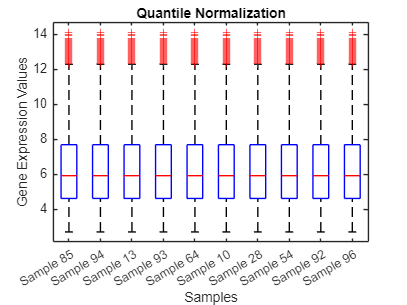



% Normalization Methods
% Quantile Normalization
quantileNormalizedData = quantilenorm(geneExpressionValues);

% Median Fold Change Normalization
medianValues = median(geneExpressionValues, 2);
medianFoldChangeNormalizedData = geneExpressionValues ./ medianValues;

% Z-score Normalization (Standardization)
zScoreNormalizedData = (geneExpressionValues - mean(geneExpressionValues, 2)) ./ std(geneExpressionValues, 0, 2);


subsetQuantileNorm = quantileNormalizedData(:, randomIndices);
subsetMedianFoldChangeNorm = medianFoldChangeNormalizedData(:, randomIndices);
subsetZScoreNorm = zScoreNormalizedData(:, randomIndices);

figure;
boxplot(subsetQuantileNorm, 'Labels', sampleLabels);
title('Quantile Normalization');
xlabel('Samples');
ylabel('Gene Expression Values');

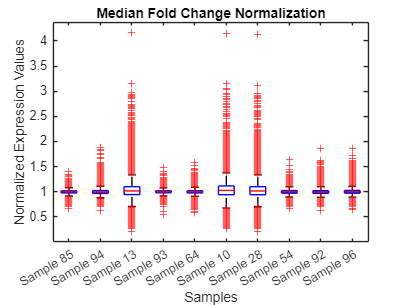


figure;
boxplot(subsetMedianFoldChangeNorm, 'Labels', sampleLabels);
title('Median Fold Change Normalization');
xlabel('Samples');
ylabel('Normalized Expression Values');

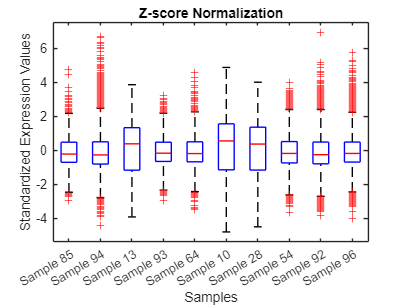


figure;
boxplot(subsetZScoreNorm, 'Labels', sampleLabels);
title('Z-score Normalization');
xlabel('Samples');
ylabel('Standardized Expression Values');

From the analysis and comparison of the three normalization methods—Quantile Normalization, Median Fold Change Normalization, and Z-score Normalization—the results indicate that **Quantile Normalization** is the most suitable approach for this dataset.**Explanation:**

## **Quantile Normalization**:

- After applying quantile normalization , the box plots show that the distribution of gene expression values across all samples has been effectively equalized.

- This method ensures that the data is comparable across samples by forcing each sample to have the same statistical distribution, which is ideal for high-throughput gene expression data.

- The consistency of medians and the uniform range across samples suggest that any technical biases have been minimized.

## **Median Fold Change Normalization**:

- While it adjusts the values relative to the median of each sample, the variation in outliers remains relatively high. This method does not equalize the variability across samples as effectively as quantile normalization.

## **Z-score Normalization**:

- Z-score normalization standardizes the data to have a mean of 0 and a standard deviation of 1. However, this method may not address the disparities in the overall distribution of gene expression values across samples as efficiently as quantile normalization.

Given these observations, **quantile normalization** achieves the best balance in reducing variability and harmonizing the distributions across all samples. Thus, it is the most appropriate normalization technique to proceed.

# **Genetic Analysis **

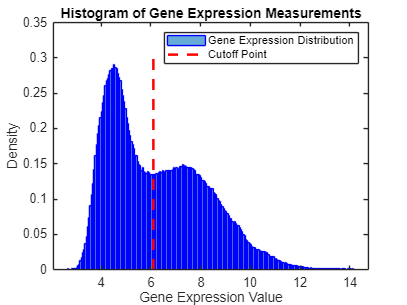

figure;
histogram(quantileNormalizedData(:), 'Normalization', 'pdf',  'EdgeColor', 'b');
hold on;

cutoff = 6.1;
yLimits = ylim;
plot([cutoff cutoff], yLimits, 'r--', 'LineWidth', 2);

title('Histogram of Gene Expression Measurements');
xlabel('Gene Expression Value');
ylabel('Density');
legend('Gene Expression Distribution', 'Cutoff Point');
hold off;

The histogram  displays the distributionof gene expression values after applying quantile normalization. This ensures that the data is properly scaled and comparable across all samples, minimizing technical noise and batch effects.

## **Gene Expression Distribution**:

- The blue bars represent the density of gene expression measurements across all samples. The normalized data shows a smooth distribution, indicating the effectiveness of quantile normalization.

## **Cutoff Point for Highly Expressed Genes**:

- A cutoff point of 6.1 (marked by the red dashed line) is used to distinguish highly expressed genes from low or moderate expression levels.

- Genes with expression values above this threshold can be identified for further analysis, such as differential expression studies, pathway enrichment, or identifying biomarkers.

This analysis helps prioritize genes for downstream research, focusing on those with significant biological relevance in the given context.


% Identify highly expressed genes using the existing cutoff
highExpressionIndices = quantileNormalizedData > cutoff;

interestingGenes = false(size(quantileNormalizedData, 1), 1);
productCategory = metadataTable.("product category");

uniqueProducts = unique(productCategory);

[~, productTypeVector] = ismember(productCategory, uniqueProducts);
for i = 1:length(uniqueProducts)
    
    productSamples = strcmp(productCategory, uniqueProducts{i});
    
    expressedInProduct = all(highExpressionIndices(:, productSamples), 2);
    
    interestingGenes = interestingGenes | expressedInProduct;

end

numInterestingGenes = sum(interestingGenes);

disp(['Number of genes expressed in all samples of at least one product: ', num2str(numInterestingGenes)]);

Number of genes expressed in all samples of at least one product: 6457


A total of **6,457 genes** were consistently active in every sample within at least one product category, categorizing them as key genes. These genes can be divided into two main groups:

### **Housekeeping Genes:**

- These genes are fundamental for maintaining essential cellular functions and exhibit stable expression levels regardless of the experimental conditions.

### **Product-Specific Genes:**

- These genes are either consistently expressed or specifically activated in response to exposure to a particular product category, indicating a targeted cellular response to that product.

# **Statistical Analysis on each Gene - T-test**

Performing t-tests for every gene to compare expression levels between the "Aerosol" and "Conventional Cigarette" groups. This approachh allows us to determine which genes show statistically significant differences in expression due to exposure to each product. The primary aim is to pinpoint differentially expressed genes that respond uniquely to either CHTP or traditional cigarette smoke, providing insights into the biological impact of each product.

productCategory = metadataTable.("product category");

group1 = 'Aerosol';           
group2 = 'Conventional Cigarette'; 

indicesGroup1 = strcmp(productCategory, group1);
indicesGroup2 = strcmp(productCategory, group2);

numGroup1 = sum(indicesGroup1);
numGroup2 = sum(indicesGroup2);
disp(['Number of samples in ', group1, ': ', num2str(numGroup1)]);

Number of samples in Aerosol: 56


disp(['Number of samples in ', group2, ': ', num2str(numGroup2)]);

Number of samples in Conventional Cigarette: 32



numGenes = size(geneExpressionValues, 1);

pValues = zeros(numGenes,1);

for i = 1:numGenes
    geneData = geneExpressionValues(i, :);
    group1Data = geneData(indicesGroup1);
    group2Data = geneData(indicesGroup2);
    
    % Perform two-sample t-test assuming unequal variances
    [~, p] = ttest2(group1Data, group2Data, 'Vartype', 'unequal');
    
    pValues(i) = p;
end

disp(['Number of p-values < 0.05: ', num2str(sum(pValues < 0.05))]);

Number of p-values < 0.05: 783


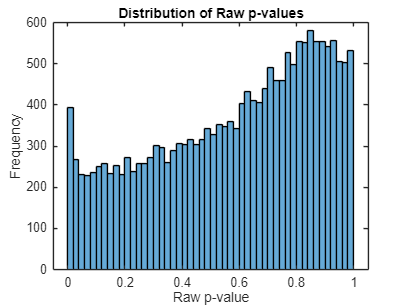


figure;

histogram(pValues, 50);

xlabel('Raw p-value');

ylabel('Frequency');

title('Distribution of Raw p-values');

### **Null Hypothesis:**

For each gene, there is no significant difference in exxpression levels between the **"Aerosol"** and **"Conventional Cigarette"** groups.

To identify genes with differential expression due to exposure to either CHTP aerosol or conventional cigarettes, we performed two-sample t-tests for each gene. This statistical approach assesses whether the mean expression levels of each gene differ significantly between the two product categories.

### **Histogram of Raw p-Values:**

The histogram  visualizes the distribution of raw p-values obtained from the t-tests across all genes. This distribution helps in understanding the overall significance of the results:

- **Peak at Low p-Values:** Indicates the presence of genes that are likely differentially expressed, rejecting the null hypothesis for those specific genes.

- **Peak at High p-Values: **hThis indicates that the presence of genes are not likely differentially expressed, accepting the null hypothesis for these genes.

### **Interpretation:**

A majority of p-values clustered around higher values (closer to 1) support the null hypothesis, indicating no significant expression differences for those genes. Conversely, a number of p-values below the significance threshold (e.g., p < 0.05) highlight genes that may be differentially expressed between the two exposure groups.

## False Discovery Rate using Benjamini-Hochberg procedure -

To account for the multiple comparisons problem inherent in performing thousands of t-tests simultaneously, the Benjamini-Hochberg (BH) procedure was employed to control the False Discovery Rate (FDR). This method adjusts the raw p-values to reduce the likelihood of false positives while maintaining statistical power.

alpha = 0.05;
adjusted_pValues = mafdr(pValues, 'BHFDR', true);
significantGenes = adjusted_pValues < alpha;

numSignificant = sum(significantGenes);
disp(['Number of significantly differentially expressed genes after BH correction: ', num2str(numSignificant)]);

Number of significantly differentially expressed genes after BH correction: 0


figure;

histogram(adjusted_pValues, 50);
title('Histogram of Adjusted p-Values (Benjamini-Hochberg)');
xlabel('Adjusted p-Value');
ylabel('Frequency');
legend('Adjusted p-Values');

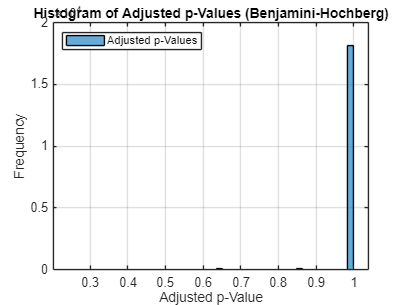

grid on;
hold off;

**Explanation:**

- **Benjamini-Hochberg Procedure:**The BH method ranks all p-values in ascending order and determines a threshold below which p-values are considered significant based on the desired FDR level (α = 0.05). This approach balances the discovery of true positives while limiting the proportion of false positives among the declared significant results.

- **Outcome:**After applying the BH correction, the analysis revealed that **zero genes** met the significance criteria (adjusted p-value < 0.05). This indicates that none of the genes showed statistically significant differential expression between the **"Aerosol"** and **"Conventional Cigarette"** groups after controlling for multiple testing.

- **Histogram Interpretation:**The histogram of adjusted p-values predominantly clusters towards at only value 1 , reinforcing the result that there are no significant differences in gene expression between the two product exposures within the parameters of this study.

# **Conclusion**

The comprehensive analysis aimed to identify genes with differential expression between cells exposed to **Carbon Heated Tobacco Products (CHTP) ** and those exposed to **conventional cigarettes**. After meticulous data extraction, normalization, and statistical testing, the following key findings emerged:

### **Normalization Effectiveness:**

- Quantile normalization was determined to be the most suitable method for harmonizing gene expression data across samples, effectively minimizing technical variability and ensuring comparability.

### **Identification of Key Genes:**

- A subset of **6,457 genes** was consistently expressed across all samples within at least one product category, encompassing both housekeeping and product-specific genes. These genes serve as a foundation for understanding baseline cellular functions and potential product-induced responses.

### **Statistical Testing and Multiple Comparison Correction:**

- Individual two-sample t-tests were conducted for each gene to assess differential expression between the "CHTP" and "Conventional Cigarette**"** groups. Subsequently, the Benjamini-Hochberg procedure was applied to control the False Discovery Rate. The stringent correction resulted in ***zero significantly differentially expressed genes****, *suggesting no detectable differences in gene expression profiles between the two exposure groups under the conditions tested.

In summary, while the current analysis did not identify any significantly differentially expressed genes between **CHTP** and **conventional cigarette** exposures after rigorous statistical correction, the foundational work lays the groundwork for more in-depth investigations into the molecular impacts of these tobacco products.